# Lab #6 FIR Filtering of Nasal Air Temperature (Two Weeks)

## Objectives:

- Create a model of input data to provide a repeatable way to test and analyze filters.

- Use fixed point representation scaling to allow faster calculations with better resolution.

- Use what you have learned about datatypes, execution time, and memory usage to optimize filter performance.

- Learn how to create the filter kernel (impulse response) for a moving average filter and a windowed sinc filter.

- Learn how to implement a FIR filter using convolution.

- Learn how to modify a filtering algorithm (datatype, scaling, and length) to work within the limitations of a given digital signal processing chip. 

## Reading

    Review Chapters 14 & 16in Smith.      

    Supplemental Reading -- "Resp Rate greater than 50 per minute as indicator of pneumonia”  

## Intended Learning Outcomes

- Demonstrate filtering of a signal using a FIR filter implemented in a microprocessor.

- Demonstrate the ability to choose appropriate variable datatypes and signal scaling for those datatypes.

- Practice communicating your results and your work in writing

## Lab 6 Arduino Code Base

CODEBASE LOCATION

### **Overview**

In this lab you will use your temperature sensor to measure nasal airflow temperature. The temperature of the air flowing over the sensor is low when you breathe in (drawing cool room air across the sensor) and high when you exhale (pushing air across the sensor that has been warmed by your lungs).  The temperature output will look somewhat sinusoidal.

From the changing temperature signal, it is possible to determine a person’s respiration rate. A respiration rate of over 50 breaths per minute can be an indication of pneumonia. As we know from sampling theory, the sample rate for data collection must be at least twice this frequency to satisfy the Nyquist criteria.

In your data collection system, you will need to collect 256 samples of temperature readings, at a sampling interval of $T_s = 100$ milliseconds. This corresponds to a sampling frequency of 10 Hz.  At this rate the Nyquist frequency is:

####  
$$Nyquist Frequency = F_s/2 = 5Hz$$


This translates to a maximum detectable breathing rate of:

####  
$$Nyquist Frequency = 5Hz = 5 \frac{breaths}{Sec}$$


####  
$$5\frac{breaths}{sec}\times60\frac{Sec}{Min}=300\frac{breaths}{Min}$$


Which is much higher than the 50 breaths per minute requirement.  With 256 samples, you will be collecting data over a time period of 25.6 seconds. 

The signal read from the LM61 temperature sensor has quantization noise and analog noise on it. To get a good signal, two filtering steps will be used. First, dithering and over sample averaging is used to get a clean signal from the ADC.  An over-sample rate of 8 will be used.  This process takes about 6.5 milliseconds for each sample average. 

After the 256 samples of temperature data is retrieved from the ADC and averaging process, the samples will be low pass filtered.  You will implement and compare the results of two different Finite Impulse Response (FIR) filters: a moving average (MAV) filter and a windowed SINC filter. Both these FIR filters are implemented using convolution as shown in the figure below.

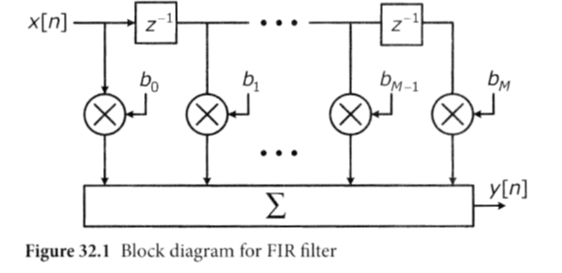

## **Section 1 -- Modeling of Breathing Data**

### **Section Discussion**

In this section you will capture real breathing data (or use a file with data already recorded for you).  The data you capture will look sinusoidal in nature with some temperature drift.  You are to create a model of the temperature data that you gathered by estimating the slope of the linear drift, the intercept of the drift, its sinusoidal frequency and amplitude, and the amount of noise on the signal.  You will capture temperature data in MATLAB and compute those values first in MATLAB and create a MATLAB model for the temperature.  Then you will implement the model of this signal with an equation within the Arduino C code.  This model will be used as the input signal for other portions of the lab to provide a consistent signal for testing so that comparisons can be made between filtering operations.

### **Description of the code**

Use the code "CodeBase_Lab06_Section1_2215.ino" from myCourses and paste it into a new Arduino sketch.  In `loop()`, 256 samples from the temperature sensor are collected and displayed.  Each sample is the average of 8 dithered subsamples from the ADC.  Each sample is converted to the ADC voltage using the equation developed in Lab 2.  Then the voltage values are  converted to temperature in degrees Celsius using the conversion equation from the LM61 data sheet.  This was also done in Lab 2.  The code is already included in the Arduino sketch.

### **Procedure**

***Collect real breathing data***

- Set up your system as done in Lab 2 to allow you to collect dithered and averaged sensor readings with ADC Vref = 5V.  Note that your dithering circuit must be connected correctly to the sensor.

- Breathe in a reasonably constant rhythm on the sensor at a slow rate, collect a sample set using MATLAB and plot the data.  With a little practice, you should obtain something like what is shown in the figure below.  Slower breathing rates around one inhale and one exhale per second will produce a better set of data for you to work with.  **NOTE:  If you are in a location where you cannot safely remove your mask then use the data provided in myCourses in the file called "Real_Breathing_Data.mat"**

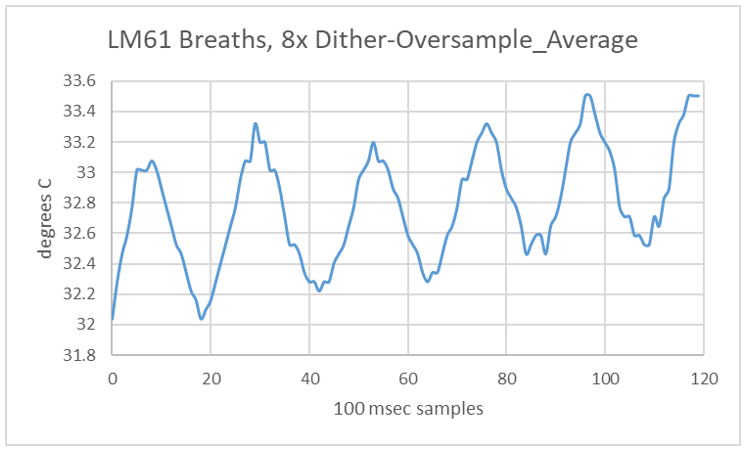

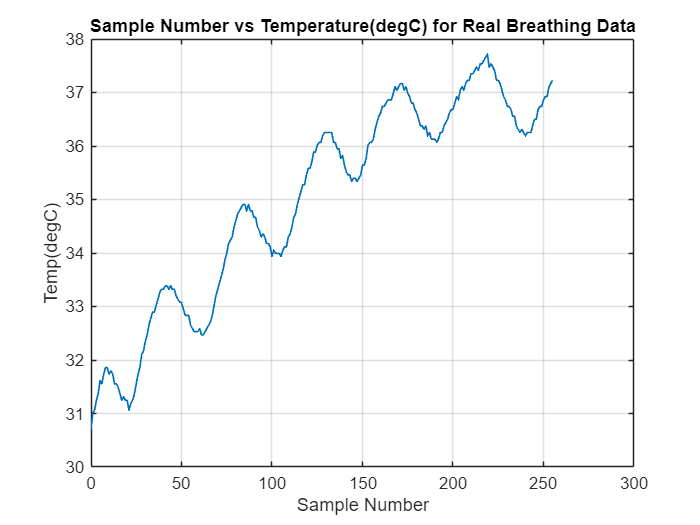

%  Load the breathing data that you recorded or use the example file
%  provided in myCourses
fileName = 'Real_Breathing_Data.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
temperature = outData(:,2);

%  Here is a summary of the steps to follow.  Place your code in the
%  section marked by SOLUTION
%
%  1.  Plot your data.  Title and label the plot
%  2.  Estimate the temperature drift as you have done in other labs using
%      the polyfit function.  Find the driftSlope and the driftIntercept
%  3.  Estimate the period of the breathing rate in samples per cycle
%      (samplesPerCycle).  Estimate this from a graph of the data with the drift
%      removed
%  4.  Estimate the peak amplitude of the sinusoid (tempP).  Estimate this from a graph of the data with the drift
%      removed
%  5.  Estimate the noise on the signal represented as a standard
%      deviation.

%  1.  Plot the original data
figure
plot(sample, temperature, 'LineWidth', 1)
grid('on');
title('Sample Number vs Temperature(degC) for Real Breathing Data')
xlabel('Sample Number');
ylabel('Temp(degC)');

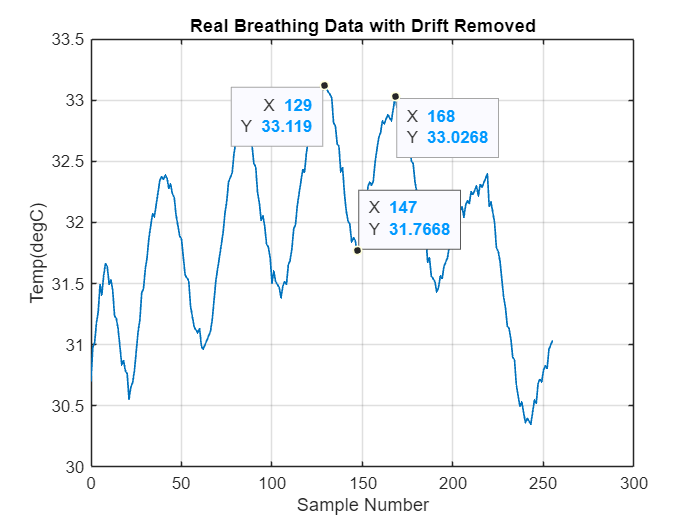

% 2.   Determine the drift parameters (linear).  Create a drift estimate and
%      remove the drift.  Plot the temperature with the drift removed.
coeffs = polyfit(sample, temperature, 1);
driftSlope= coeffs(1);
driftIntercept = coeffs(2);  % Only use if you want to remove the offset too

driftEstimate = driftSlope * sample;
noDrift = temperature - driftEstimate;

% Plot
figure
plot(sample, noDrift, 'LineWidth', 1)
grid('on');
title('Real Breathing Data with Drift Removed')
xlabel('Sample Number');
ylabel('Temp(degC)');

% Code for graph datatips
ax = gca;
chart = ax.Children(1);
datatip(chart,168,33.03);
datatip(chart,129,33.12,"Location","southwest");
datatip(chart,147,31.77);

%  3.  Estimate the period of the breathing rate from the graph in samples per
%  cycle.
samplesPerCycle = 168 - 129;

% Convert this to breaths per minute (bpm) using:
%  bpm = 1/samplesPerCycle * 10 Samples/Sec * 60 Sec/Min
%
%  Create a variable that represents the period of breathing in breaths per
%  minute
bpm = (1 / samplesPerCycle) * 10 * 60

bpm = 15.3846

%  4. Estimate the peak to peak amplitude (tempP) of the sinusoid from the graph.
%  Create a variable that represents the peak amplitude of the temperature
%
tempP = 33.119 - 31.7668

tempP = 1.3522

***Create a repeatable model of the breathing data***

In the following exercises, you will examine the effects of various filter designs on breathing signals like this.  In order to make meaningful conclusions about comparative filter performance, you will need a repeatable breathing signal.  You will model the breathing signal using an equation that includes a time varying temperature, a temperature drift and noise.

####  
$$T = T_0 +T_{drift}*n+T_{p}sin(2\pi\times n/(\frac{samples}{cycle}))+T_{noise}$$


Where $T_0$  is the average temperature (drift intercept), $T_{drift}$  is the rate of temperature drift (drfit slope), $T_{p}$ is the peak temperature variation, samples per cycle is the period of the breathing rate,   $T_{noise}$ is uniformly distributed noise and n is the sample number.

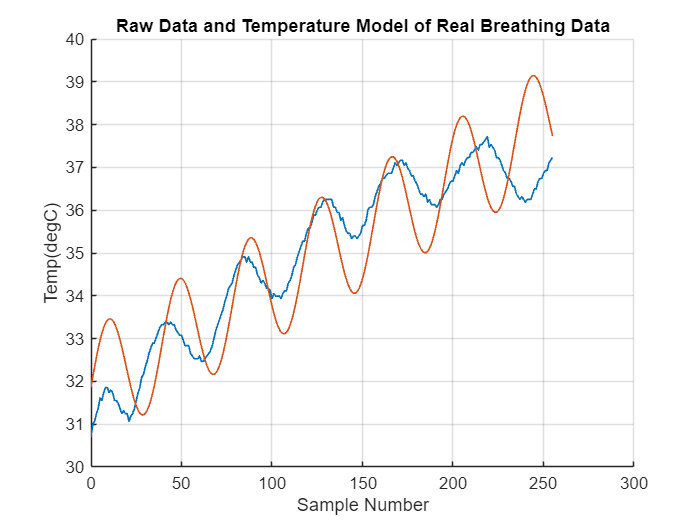

%  Create a model of the signal in MATLAB so that you can compare it to the
%  real breathing data.  You can then use these parameter estimates in your C
%  code and again compare to make sure your C code is correct
%
%  The signal model equation uses samplesPerCycle.  The C code will do the
%  conversion from bpm to samplesPerCycle for later convenience
%
%  First create the signal model equation without noise.  This will allow
%  you to check the slope and frequency
tempModel = driftIntercept + driftSlope * sample + tempP*sin(2*pi*sample/samplesPerCycle);

%  Plot the temperature model and the real breathing data on the same graph
figure
hold('on');
plot(sample, temperature, 'LineWidth', 1)
plot(sample, tempModel, 'LineWidth', 1)
hold('off');
grid('on');
title('Raw Data and Temperature Model of Real Breathing Data')
xlabel('Sample Number');
ylabel('Temp(degC)');

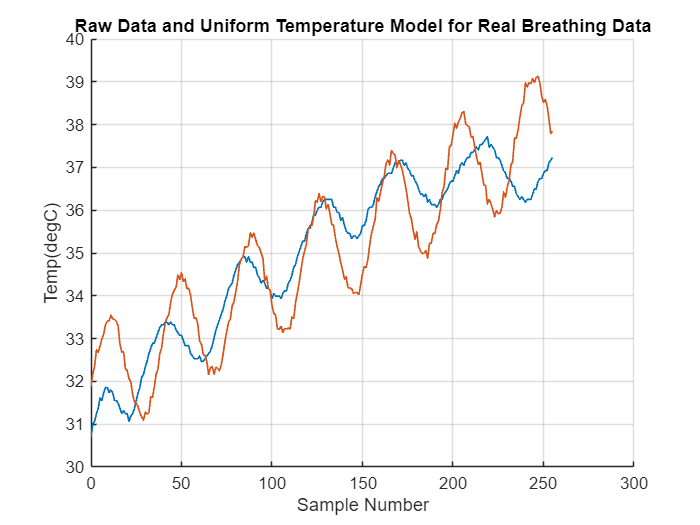

%  5.  Estimate the standard deviation of the noise 
%
%  Now add noise.  The noise is a uniform random variable with a SD of 1
%  degC.  It is scaled by your value of sigma, which you will determine
%  empirically (manually adjust the value).  Add the uniform noise to the
%  your model as shown below
%
%  Create a variable that is a uniform random variable with a SD of 1 deg c
noiseUniform = ( rand(length(sample),1) -.5 )/.29;   %  Uniform random  with SD of 1 degC

%  This noise value will be scaled by a variable sigma so that you can
%  adjust the noise.  You will adjust this manually to match the real
%  breathing
sigma = 0.1;
tempModelUniform = driftIntercept + driftSlope * sample + tempP*sin(2*pi*sample/samplesPerCycle) + sigma * noiseUniform;

%  Plot the model equation on top of the real breathing data for comparison.
%  It doesn't have to be exact, something close will be fine.  Adjust the
%  noise sigma empirically to be close.
figure
hold('on');
plot(sample, temperature, 'LineWidth', 1)
plot(sample, tempModelUniform, 'LineWidth', 1)
hold('off');
grid('on');
title('Raw Data and Uniform Temperature Model for Real Breathing Data')
xlabel('Sample Number');
ylabel('Temp(degC)');

***Use the default model of breathing data***

Create a signal model in the C code by comment deselecting `analogReadDitherAveDegC() `and comment selecting `simulateBreathingDegC()`as the sample source.  The simulation return is composed of a constant level (room temperature) plus a ramp (warm up drift) plus a sine wave (breathing temperature cycle) plus a random variable (sensor noise).  Enter the variables that you calculated in MATLAB into the C code.  Run the sketch and plot the simulated breathing output and compare it to the real breathing data and the MATLAB model.

Include the values of your breathing rate model in your lab report.

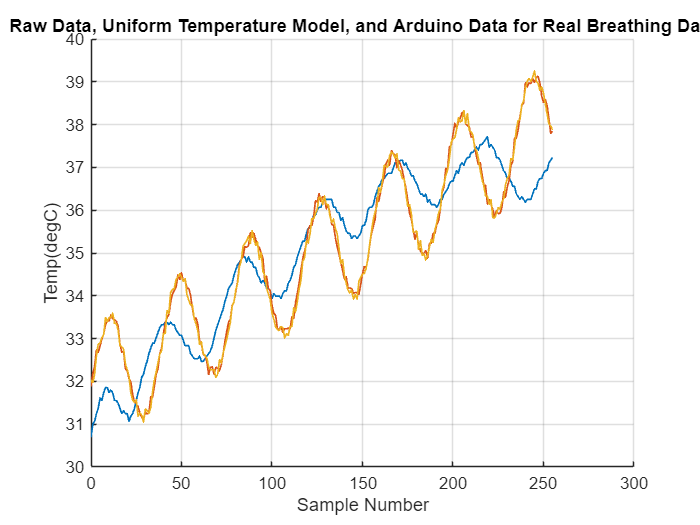

%  Once you have found acceptable values for the model.  Transfer those
%  values to the C Code.  Run the C-code model and capture data in MATLAB.
%  Plot all three temperature plots on the same graph
fileName2 = 'Arduino_Breathing_Data.mat';
load(fullfile(pwd, fileName2));
temperatureArduino = outData(:,2);

figure
hold('on');
plot(sample, temperature, 'LineWidth', 1)
plot(sample, tempModelUniform, 'LineWidth', 1)
plot(sample, temperatureArduino, 'LineWidth', 1)
hold('off');
grid('on');
title('Raw Data, Uniform Temperature Model, and Arduino Data for Real Breathing Data')
xlabel('Sample Number');
ylabel('Temp(degC)');

***Run the model faster than normal by changing ***`TSAMP_MSEC`

- Set `TSAMP_MSEC` = 10 and observe that the model output is unchanged.  This is just done to decrease the amount of time to get a full display. 

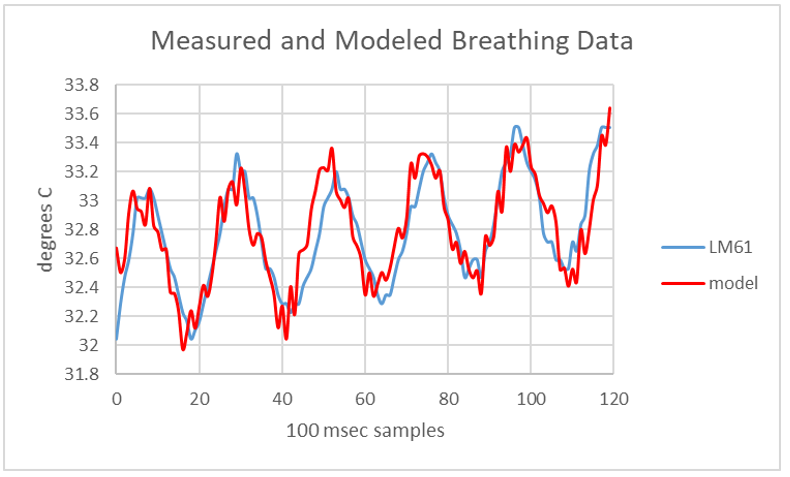

## **Section 2 – Fixed point data representation and scaling**

### **Section Description**

In this section you will use the breathing model that you created in section 1 and collect data in different ways to show how it can be represented as a float and a fixed point number even with a fractional portion.

Recall that floating point numbers can represent numbers with fractions.  Fixed point numbers can only represent integer values.  However, if we take a floating point number with a fractional portion we can scale that number by factors of 10 (1,10,100,1000) and then use a fixed point number to represent that fractional number as long as we keep track of the scale factor.

For example if we have a floating point number 33.4582 if that gets converted to a fixed point value it will be represented as 33.  If it is scaled by 10 first then converted to fixed point it will be 334 which represents the value 33.4 when scaled back down.  If it is scaled by 100 then converted to fixed point then the value is 3345 which represents 33.45 when scaled back down by 100.  In this way we can used fixed point numbers to represent fractional values.

When the conversion to a fixed point number is done, there is a rounding process that happens which leads to some amount of error or quantization noise.

When scaling the number we also have to be careful not to scale it so large that it cannot be represented properly in the fixed point number system we have chosen.

***Why fixed point?***

From Lab 3, you know that integer and long datatype computations are much faster than floating point computations.  Fixed point arithmetic enables integer storage of data by rescaling units to the finest precision value required for a problem, and then choosing an integer data type (`int `or `long`) to cover the required range.

*An illustration of the technique*

Temperature measurements in our system exhibit an SNR no better than about 30 dB (~32:1) for a 1 °C pk-pk amplitude square wave temperature excursion, so there is no need to represent incremental temperatures less than 0.01°C or 1 centi-degree Celsius (cC).  Assume a working temperature range of -10 °C to +50 °C or -1000 cC to +5000 cC.  Then we can represent all meaningful temperatures with integer variables (INTs) with resolution of 1 cC.  For example, the floating point value 27.73 °C is stored as the integer 2773 cC.  Each sample measurement now requires just 2 bytes of memory for an INT instead of 4 bytes for a FLOAT, and computational speed is advantaged.

If the SNR of the sensor were 60 dB, we would choose a unit of 0.001C or 1 milli-degree Celsius (mC).  The operational range would be -10,000 mC to +50,000 mC, so a datatype of LONG variables would be required to store the number because they would exceed the range of an INT.  Each measurement value would require the same 4 bytes as it would if it were stored as a FLOAT, but speed would still be advantaged.

### Description of the code

For this section of the lab start with the code file in myCourses named "CodeBase_Lab06_Section2_2215.ino".

This code uses the model of the temperature sensor from section 1 with some modifications to the parameter values.

This code will return 4 values for each sample gathered.  The 1st column is the sample number.  The 2nd column is a floating-point number representing the temperature.  This is in the 2nd column and is the variable fltX in the C code.

The 3rd column is also a floating point number but it is the temperature value scaled by a constant in the code DATA_FXPT which will be set to 1, 10, 100 and 1000 during the procedure.  It is the variable scaleFltX in the C code.

The 4th  column is a fixed point number that is the scaled floating point number converted to an integer value.  The conversion to fixed point rounds the value to the nearest integer and will effectively add quantization noise to the value.  It is the variable fxptX in the C code

The 5th column of data is the difference between the scaled floating point number in column 3 and the fixed point value in column 4  

### **Procedure**

1. Modify the breathing temperature model parameters so that the signal has an average value of 33 °C (driftIntercept = 33.0),  no drift (driftSlope = 0.0), no noise (sigma = 0.0) and a breathing rate of 10 bpm with a magnitude of 0.6 °C peak.

2. Start with the value of DATA_FXPT set to 1.  Run the Arduino code and capture data in MATLAB.  Column 5 contains the error between the scaled fixed-point value and the scaled floating-point value.  Compute the standard deviation of the error.  This is the noise of the signal.  Calculate the signal level by computing the standard deviation of the scaled floating-point value in column 3.

Repeat the measurements for DATA_FXPT = 1, 10, 100, and 1000, respectively.  Complete a table of your results like the one shown below.  Include a short paragraph in your report interpreting your results.

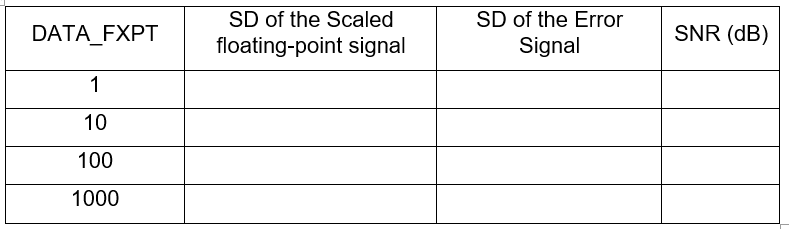

3. Plot an overlay of scaled float-point values and the scaled fixed point values for each value of the scale factor.  Plot the associated quantization error plots in the manner shown below for DATA_FXPT = 1 to inform your understanding.  The error plots need not be included in your report.

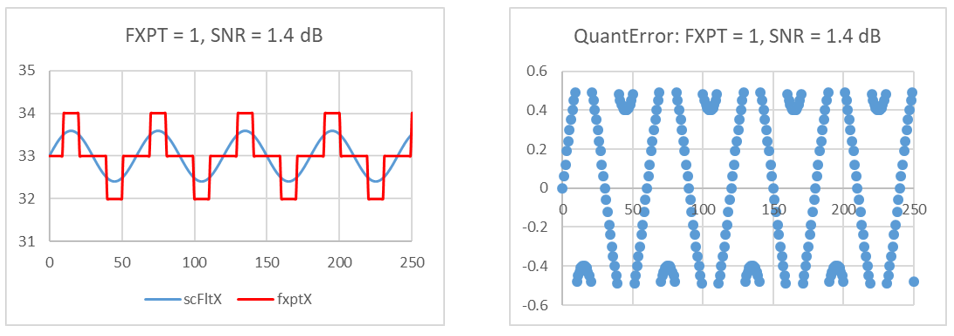

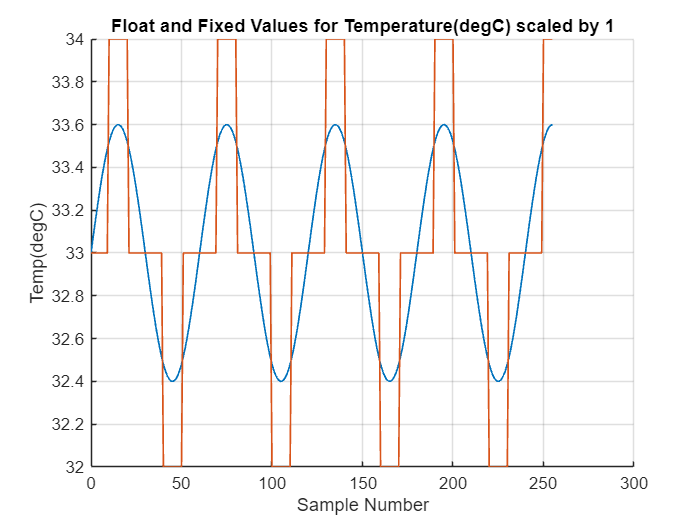

clear;  % Clear workspace

%  For each value of DATA_FXPT capture data and compute the standard
%  deviation of the error and the standard deviation of the scaled floating
%  point signal.  Plot the scaled fixed point value and the scaled floating point
%  value on the same graph for each value of DATA_FXPT

%  SOLUTION DATA_FXPT = 1
load(fullfile(pwd, 'section_2_1.mat'));
sample1 = outData(:,1);
temperatureFloatScaled1 = outData(:,3);
temperatureFixed1 = outData(:,4);

figure
hold('on');
plot(sample1, temperatureFloatScaled1, 'LineWidth', 1)
plot(sample1, temperatureFixed1, 'LineWidth', 1)
hold('off');
grid('on');
title('Float and Fixed Values for Temperature(degC) scaled by 1')
xlabel('Sample Number');
ylabel('Temp(degC)');

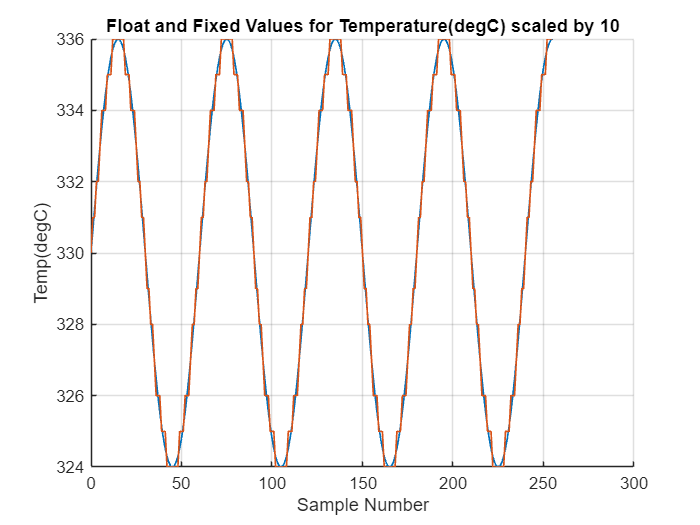

%  SOLUTION DATA_FXPT = 10
load(fullfile(pwd, 'section_2_2.mat'));
sample2 = outData(:,1);
temperatureFloatScaled2 = outData(:,3);
temperatureFixed2 = outData(:,4);

figure
hold('on');
plot(sample2, temperatureFloatScaled2, 'LineWidth', 1)
plot(sample2, temperatureFixed2, 'LineWidth', 1)
hold('off');
grid('on');
title('Float and Fixed Values for Temperature(degC) scaled by 10')
xlabel('Sample Number');
ylabel('Temp(degC)');

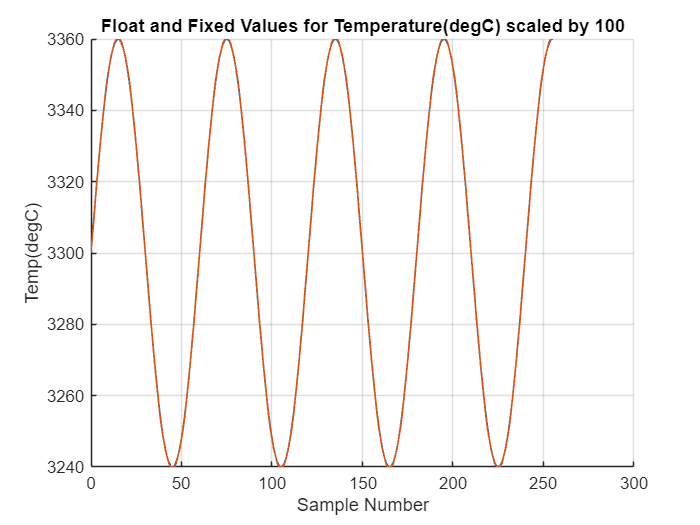

%  SOLUTION DATA_FXPT = 100
load(fullfile(pwd, 'section_2_3.mat'));
sample3 = outData(:,1);
temperatureFloatScaled3 = outData(:,3);
temperatureFixed3 = outData(:,4);

figure
hold('on');
plot(sample3, temperatureFloatScaled3, 'LineWidth', 1)
plot(sample3, temperatureFixed3, 'LineWidth', 1)
hold('off');
grid('on');
title('Float and Fixed Values for Temperature(degC) scaled by 100')
xlabel('Sample Number');
ylabel('Temp(degC)');

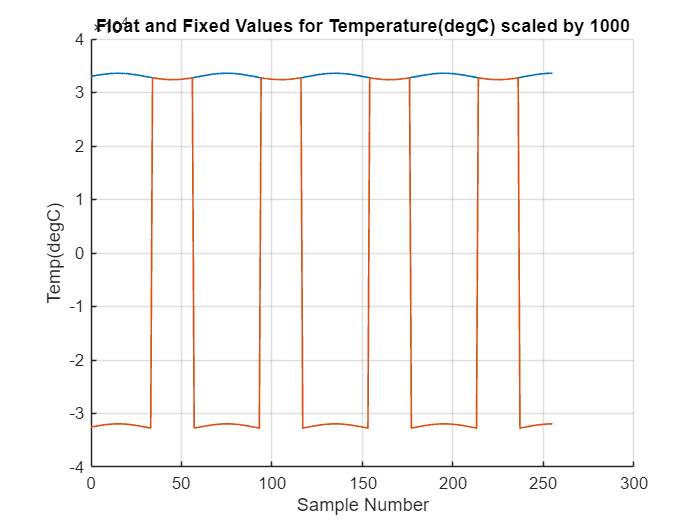

%  SOLUTION DATA_FXPT = 1000
load(fullfile(pwd, 'section_2_4.mat'));
sample4 = outData(:,1);
temperatureFloatScaled4 = outData(:,3);
temperatureFixed4 = outData(:,4);

figure
hold('on');
plot(sample4, temperatureFloatScaled4, 'LineWidth', 1)
plot(sample4, temperatureFixed4, 'LineWidth', 1)
hold('off');
grid('on');
title('Float and Fixed Values for Temperature(degC) scaled by 1000')
xlabel('Sample Number');
ylabel('Temp(degC)');

## **Section 3 - FIR filtering with Moving Average Filter**

### **Overview**

A moving average filter will be implemented to smooth out sensor noise.  Input/output data is represented in centi-degrees C by setting the value of DATA_FXPT = 100.  Observe the tradeoff of MAV kernel length, noise suppression, and breathing signal attenuation.

Recall that a moving average filter has an impulse response that is a constant value for all samples.

### **Description of the code**

Copy the code "CodeBase_Lab06_Section3_2215.ino" into a new Arduino sketch.  In` setup(), `you can comment select functions to generate floating point coefficients for a Moving Average (MAV) or sinc FIR filter kernel.

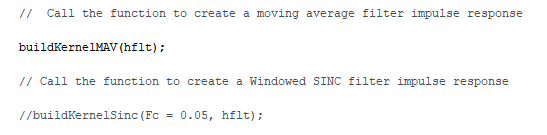

Coefficients of the filter kernel are displayed to the command window before data collection begins.  This can be enabled by comment selecting the call to the function "displayKernel".

In loop(), a fixed point temperature signal is simulated and convolved with the filter kernel.  The input and convolution output can be captured in MATLAB as fixed point integers.

### **Procedure**

1. A linear phase sinc kernel needs an odd number of elements so that it is symmetric about the center sample.  The constant MFILT in the C Code is the number of kernel samples, so 0 is the lowest index and MFILT-1 is the highest index.  MFILT = 6 (n = 0,1,2,3,4,5) is not symmetrical.  MFILT = 5 (n = 0,1,2,3,4) is symmetric about sample 2.  Set `MFILT` = 11 and comment select "buildKernelMAV" function call to create a MAV filter kernel in `setup()`.  

2. Create a simulated breathing signal that exhibits zero drift (driftSlope = 0.0), 30 °C mean (driftIntercept = 30), 0.6 °C peak (tempP = 0.6) at 12 bpm, and 0.05 °C rms noise (sigma). Modify the variables in the simulatedBreathFxptDegC function.  Generate values in fixed point Celsius by setting the value of the constant DATA_FXPT = 100.  Recall that a temperature value of 33.45 will then be represented in fixed point number as 3345.

3. Run the code on the modeled temperature data.  Capture the values of the input X and the output Y in MATLAB.  The 1st column is the sample number, the 2nd column is the value of the variable fxptX and the 3rd column is the value of the variable fxptY.  Plot X and Y on the same plot and add an appropriate title and axes labels.  Note that X and Y are not the X and Y axes but rather the two signals that you captured.

4. Observe the unusual filter output over the first 11 (MFILT) samples.  This is expected and corresponds to the number of cycles required to fill the data buffer used in the point-wise multiplication and addition operations of convolution.  To facilitate auto-scaling of charts, replace the first MFILT elements of the output with the filter input values.  This can be done within the C code by uncommenting the line within the "floatKernelFIR" function.  The line is shown in the code below.

These outputs are equally meaningless as the ramp elements, but they are convenient for plotting.

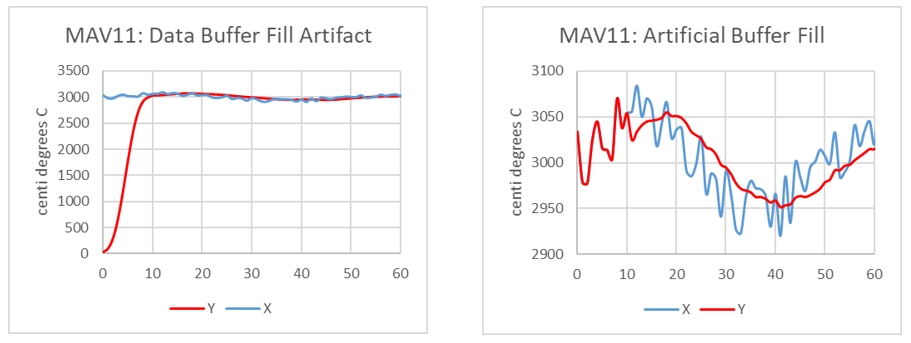

4. Plot the input to the filter and the output of the filter on the same plot for each case of MFILT = 11 and MFILT = 41.  Write a short paragraph describing the impact of kernel length on the number of valid output samples and on output signal and noise amplitudes relative to the corresponding input signal components.

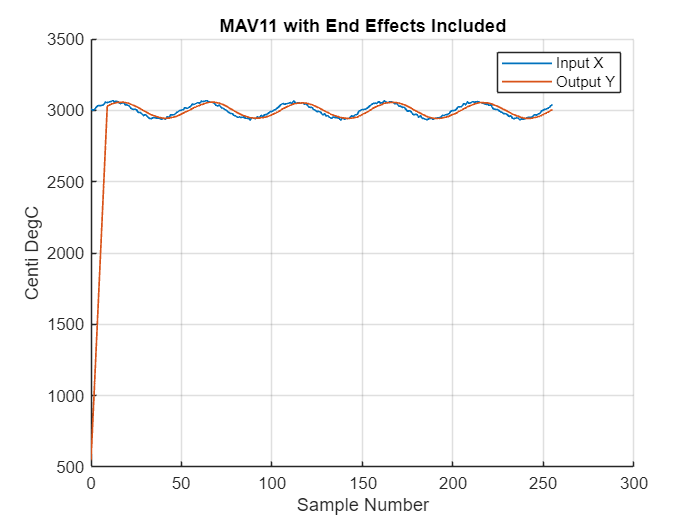

%  Load the file with the MAV filter input and filter output for MFILT = 11
clear
load(fullfile(pwd, 'section_3.mat'));

%  Plot the result with end effects included
figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('MAV11 with End Effects Included')
xlabel('Sample Number');
ylabel('Centi DegC');

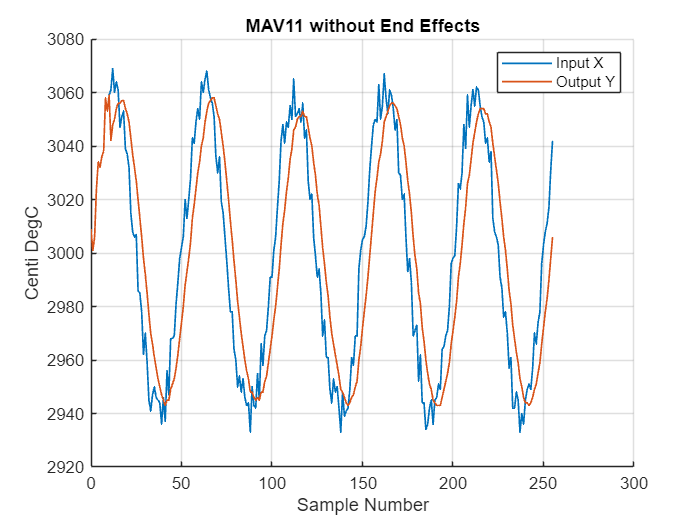

%  Plot the result without end effects included
load(fullfile(pwd, 'section_3_mav11_buffer.mat'));

figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('MAV11 without End Effects')
xlabel('Sample Number');
ylabel('Centi DegC');

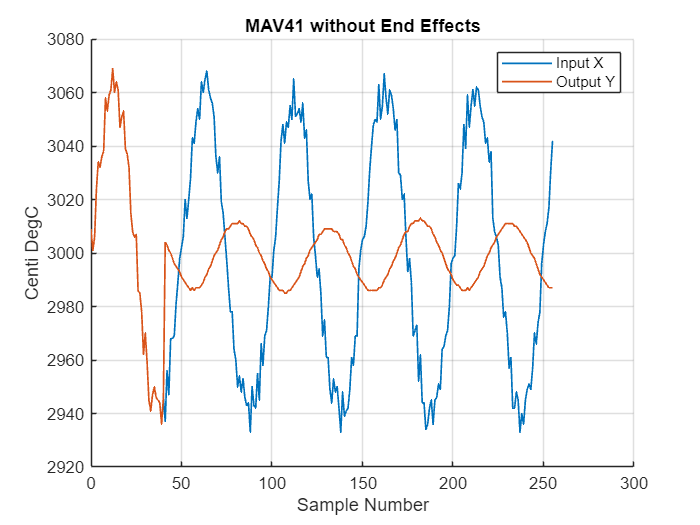

%  Load the file with the MAV filter input and filter output for MFILT = 41
load(fullfile(pwd, 'section_3_mav41.mat'));

%  Plot the result without the  effects included
figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('MAV41 without End Effects')
xlabel('Sample Number');
ylabel('Centi DegC');

Question 4.

Kernel length negatively impacts the number of valid output samples, as the number of end effects is determined by the length of the filter kernel. In this application, the length of the filter kernel also affects the number of usable values at the beginning, as the filter input is passed directly to the output until the input buffer is filled. This is most prominently displayed with the MAV41 filter, as an entire period of the input signal is passed through until the buffer is filled. Kernel length aso has a negative impact on the output signal amplitude, as a longer filter kernel creates an output with an amplitude much smaller than the input.

## **Section 4 - FIR filtering with Windowed Sinc Filter**

### **Overview**

The filtering of the 256 samples can be improved by using a windowed sinc filter kernel, which is better at isolating and attenuating high frequencies than the moving average filter.

### **Procedure**

Use the same code as in Section 3

1. Comment deselect the `buildKernelMAV()` function call in `setup()` and comment select `buildKernelSinc()`.  Set Fc = 0.05 in the call.  Fc is the corner frequency of the filter expressed as a fraction of the sampling frequency.  The sampling period is 100 msec, corresponding to a sampling frequency of 10 Hz.  Compute the normalized corner frequency by dividing the desired corner frequency by the sampling frequency.

#### 
$$F_{c(norm)}=\frac{F_c}{F_s }$$


To set the filter corner to match a specific breathing rate (bpm), convert the breathing rate in breaths per minute to breaths per second and divide by the sampling frequency.

#### 
$$F_{c_{norm}}=\frac{bpm(\frac{1}{60}\frac{min}{sec})}{F_s}$$


As an example, to set the corner frequency to match 30 breaths per minute set the variable $F_c$ as

#### 
$$F_c = \frac{(30)(\frac{1}{60})}{10 Hz}=0.05$$


2. Set MFILT = 11 and run the code on the same simulated breathing signal as you used for the MAV case.  

3. Capture the input and output data from the filter in MATLAB. Note the sum of the kernel samples reported after sample enumeration.  This can be seen at the top of the command window before input and output data is displayed.  

4. Plot the input and output samples.  What is the DC gain of the system for samples beyond the first MFILT samples?  The gain is the ratio of the filter output to the input signal.

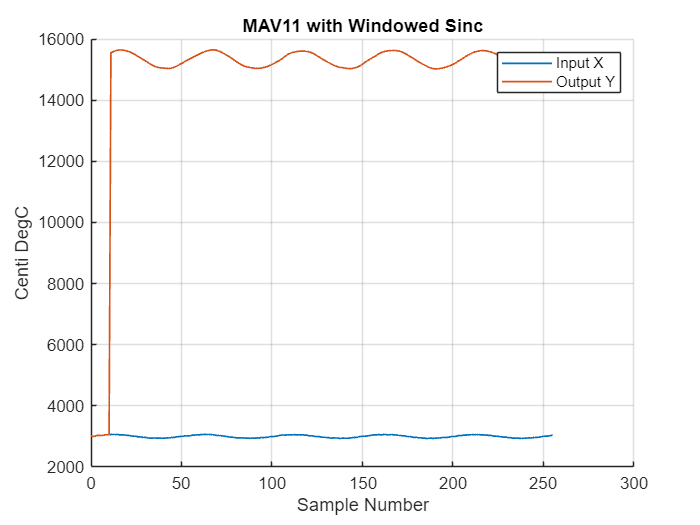

%  Plot the results of filtering with the Windowed SINC filter for length
%  MFILT = 11.  
clear
load(fullfile(pwd, 'section_4.mat'))

figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('MAV11 with Windowed Sinc')
xlabel('Sample Number');
ylabel('Centi DegC');

**Because filter kernel size is equal to 10, the first 10 output values will not be good, as the filter is buffering in the values (hence the jump in the graph)**

5. The DC gain of a FIR filter is the output of the filter for input samples that are all 1.  It can be found by summing all the values of the impulse response.  To normalize the filter gain to 1 the impulse response is scaled by 1 divided by the sum of the impulse response values.

6. Modify the `buildKernelSinc`() function to generate DC gain = 1.0 for any MFILT in the code section below.

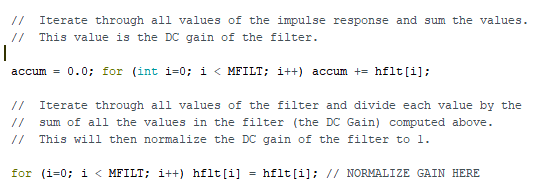

7. Plot the filter input and the filter output on common axes for each case of MFILT = 11 and MFILT = 41 with the DC gain set to 1.0.  Write a short paragraph describing the impact of kernel length on the number of valid output samples and on the output signal and noise amplitudes relative to the input signal components.

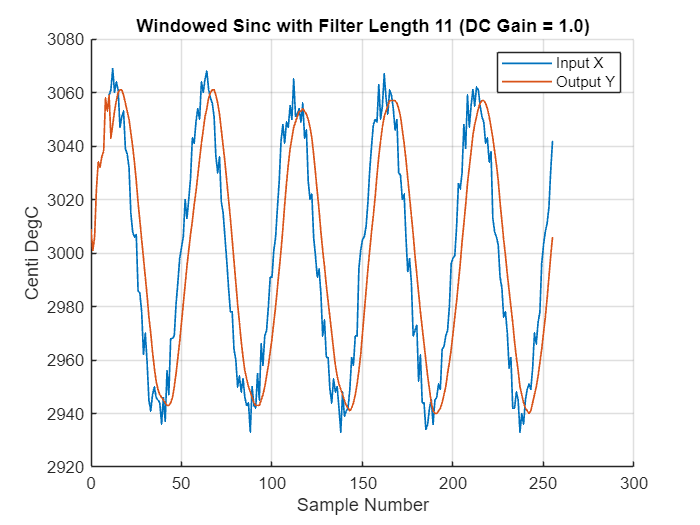

%  Plot the results of filtering with the Windowed SINC filter for length
%  MFILT = 11 and 41 with the DC gain set to 1.0
load(fullfile(pwd, 'section_4_mav11.mat'))

figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('Windowed Sinc with Filter Length 11 (DC Gain = 1.0)')
xlabel('Sample Number');
ylabel('Centi DegC');

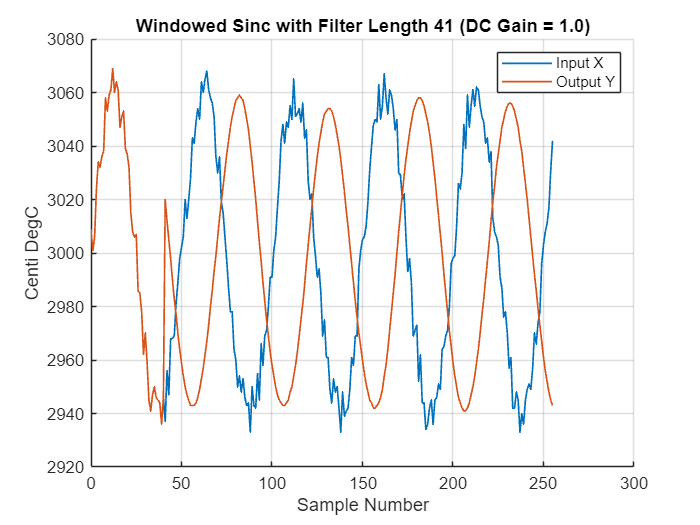

load(fullfile(pwd, 'section_4_mav41.mat'))

figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('Windowed Sinc with Filter Length 41 (DC Gain = 1.0)')
xlabel('Sample Number');
ylabel('Centi DegC');

Kernel length determines how many filter output values in the beginning are valid. The graph above shows that the moving average filter only begins to take effect after 41 samples, which is the length of the filter kernel. This is because we are directly passing in the input values to the filter output to avoid end effects, which is also why the input samples only begin at 41 as well. Kernel length also has a time-shifting effect on the filter output signal as a larger kernel means a longer computation time before the filter can output a value.

## **Section 5 – Fixed Point FIR Filter Convolution**

### **Overview**

In Lab 5 you documented the speed advantages of integer over floating point math.  In this section, you will convert the filter kernel from floating point values to fixed-point integers and investigate the speed consequences of fixed point implementation choices.

Copy the code in file "CodeBase_Lab06_Section5_2215.ino" from myCourses and paste it into a new Arduino sketch.  In` setup(),`a sinc kernel is computed in floating point for a specified MFILT and scaled by HFXPT.  This creates an impulse response  using fixed point values that are integers  similar to the way that the floating point temperature data was scaled to create a fixed point integer.  The scale factor for the impulse response is HFXPT.

The floating point, scaled floating point, and the fixed point integer SINC filter coefficients are displayed to the command window along with kernel sample sums.  When a unity gain kernel is expressed in fixed point, its DC gain is HFXPT because of the scaling.  In loop(), a fixed point temperature signal is simulated and convolved with the fixed point filter kernel.  The input and convolution output are displayed in the console as fixed point integers.

Recall that the convolution sum generates each output point as the sum of products of current and past input samples with N = MFILT kernel elements.

#### 
$$y[n]=\sum_{i=0}^{N-1}h[i]x[n-i]$$


When we express x[n] in fixed point notation with scaling DFXPT, y[n] is automatically scaled by DFXPT.  We can recover the original scaling of the measurement by dividing the convolution output by DFXPT if we choose, though generally we do so only for display.  Cascaded convolution operations preserve the scale of the original input.


$$DFXPT*y[n]=\sum_{i=0}^{N-1}h[i](DFXPT*x[n-i])$$



$$y_{fxd}[n] = \sum_{i=0}^{N-1}h[i]x_{fxd}[n-1]$$


When we express h[n] in fixed point with scaling HFXPT, y[n] is scaled as well, but not x[n].   Cascaded convolution operations result in exponential scale growth unless the output of each operation is scaled down by HFXPT.

#### 
$$HFXPT*y_{fxd}[n]=\sum_{i=0}^{N-1}(HFXPT*h[i])x_{fxd}[n-i]$$


#### 
$$y_{fxd}[n]=(1/HFXPT)\sum_{i=0}^{N-1}h_{fxh}[i]x_{fxd}[n-i]$$


Division is slow, so the 1/HFXPT factor is usually computed at compile time and implemented through multiplication.

The running summation is implemented as the accumulation of N individual h[ ]*x[ ] products in a loop. Because both h[n] and x[n] are 16 bit entities, their product is a 32 bit entity.  We will eventually scale the sum of products back down to a 16 bit entity when we divide by HFXPT, but until the sum is complete, we need to provide space for the intermediate result.  We do this by temporarily casting either h[ ] or x[ ] to a type with adequate range to handle the worst case accumulation.  The compiler will automatically cast the other element to the same type when doing arithmetic. The fastest assignment that can be made for a given data type is to a variable of the same type, so we should always make the temporary cast to the same type as the accumulator variable.  Our two choices are `float` and `long`.

### **Procedure**

1. Set MFILT = 41, Fc = 0.05, DATA_FXPT = 100, HFXPT = 100, and run the code on the same modeled temperature as in the previous section.  Note the sum of kernel samples reported after sample enumeration. Note the sum of the values of the fixed point filter kernel are zero due to rounding of the floating point values.  Why does this occur?  If we constrain HFXPT to be a power of 2, what is the minimum value that guarantees |hfxpt[n]| ≥ +/-1 for all non-zero elements of hflt[n]?  That is, what value would I have to multiply the smallest kernel value by to guarantee that it is greater than or equal to +/-1?

%  Find the minimum value of the kernel (by observation of values in the
%  command window)  Find the minimum power of 2 (i.e. 2^X) that is required
%  to keep the value in the kernel greater than or equal to 1
clear

HFXPT = 2^11

HFXPT = 2048

2. For DATA_FXPT = 100, MFILT = 41, and HFXPT from step 1, what is the maximum value of the fixed point convolution sum (prior to division by HFXPT) for a 50 °C DC input?  Confirm your estimate by simulating breathing around a 50 C mean and back calculating the intermediate accumulator from the output.  (i.e. by multiplying it by HFXPT).  Can this value be represented as a float?  Can this value be represented as a long?

%  With the mean value of temperature set to 50 find the maximum value of
%  the accumulator by finding the maximum value of the output of the filter
%  and multiplying by HFXPT from step 1.
load(fullfile(pwd, 'section_4_mav11.mat'))

maxVal = max(outData(:,3));
accumMax = maxVal * HFXPT

accumMax = 6268928

3. Write a short paragraph justifying your choice of `float` or `long` accumulation for a fixed point convolution implementation of our system.  Discuss precision and range requirements.  Include speed measurements for both choices.

4. Plot fxptX and fxptY on common axes for MFILT = 41. Plot the difference between the outputs for the floating point and fixed point kernel implementations for both accumulator types (FLOAT and LONG).  For each accumulator type, consider the floating point SINC filter output as the ‘gold standard’ signal.  The error is the difference of each output and the ‘gold standard’.  Plot the error between the filter types.

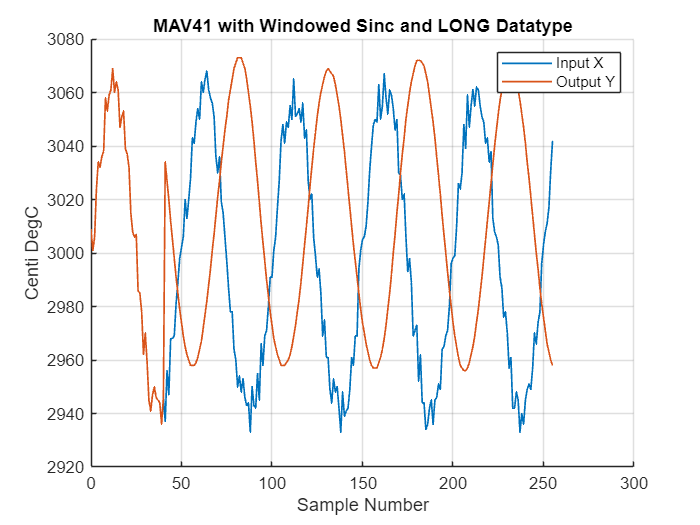

%  Plot the output of the SINC filter for LONG and FLOAT implementations.
load(fullfile(pwd, 'section_5_long.mat'))

figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('MAV41 with Windowed Sinc and LONG Datatype')
xlabel('Sample Number');
ylabel('Centi DegC');

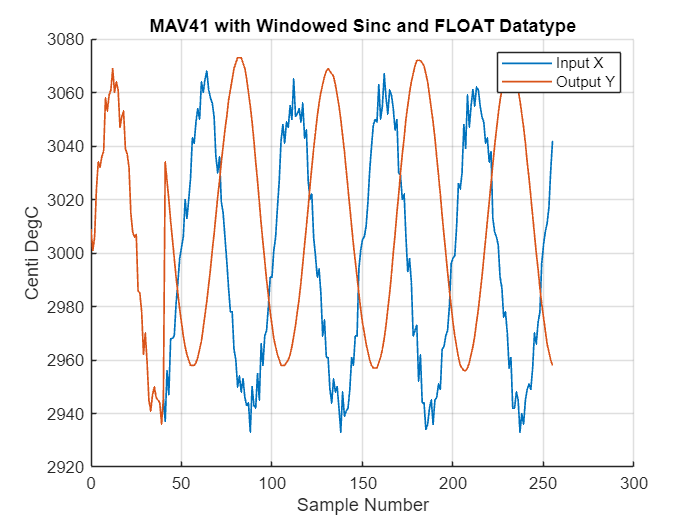

load(fullfile(pwd, 'section_5_float.mat'))

figure
hold('on');
plot(outData(:,1), outData(:,2), 'LineWidth', 1)
plot(outData(:,1), outData(:,3), 'LineWidth', 1)
hold('off');
grid('on');
legend('Input X', 'Output Y');
title('MAV41 with Windowed Sinc and FLOAT Datatype')
xlabel('Sample Number');
ylabel('Centi DegC');

%  Compute the error between the LONG and FLOAT implementations.







% Compute the error of the fixed point to the floating point filters.
% Plot the error

%  SOLUTION



### **Write up**

Lab 6 addresses four major issues.  Your write up should demonstrate understanding and serve as a high-level tutorial for all four.  Use the IEEE report format.  The following is a guide.

- Signal conditioning and modeling.  Show an overlay plot of `float` samples of LM61 measured breathing and modeled breathing, scaled in degrees Celsius.  Show a code snippet of the model with your parameters applied.  Include a short paragraph describing model operation.

- Fixed point data representation.  Write a short paragraph describing the choice of fixed point scaling (scale factor DATA_FXPT 1, 10, 100, 100) mC) and integer type (`int`, `lon`g) for the breathing temperature problem.  Show charts of modeled breathing data comparing scaled float and fixed point representations for scale values  DATA_FXPT of 100 and 1000. Explain the problem with DATA_FXPT = 1000 and how DATA_FXPT = 100 is acceptable in terms of assumed data range and precision.

- Compare MAV and SINC filter performance.  Show plots of MAV and sinc filtered model data for filter kernel lengths 11 and 41 (4 charts all together).  Comment on the relative merits of MAV versus LPF sinc filtering for improving the SNR of the raw breathing signal (signal in vs. out, noise in vs. out).

- Fixed point FIR filter implementation.  Justify your choice of sinc kernel fixed point (HFXPT) in terms of minimum kernel element size for the MFILT = 41 case. Justify your choice of convolution accumulator variable type in terms of kernel DC gain and maximum input signal amplitude.  Use a table to report the per-point execution times of the MFILT = 41 sinc filter using a floating point kernel, a fixed point kernel with a `float` typed accumulator, and a fixed point kernel with a `long` typed accumulator.  Show plots comparing filter outputs when processing modeled breathing data for your float and fixed point kernel designs.

### Lab Report Rubric